
$$Y(t) = -a_1y(t-1) +b_1u(t-2) +e(t)$$


%% Métodos de optimización PEM. Newton-Raphson.
% Autor de código base: Carlos Mario Véles S.
a1 = 0.2476; b1 = 0.2233; Gd = tf(b1,[1 a1], 'Ts',1, 'InputDelay', 1) % Modelo

Gd =
 
             0.2233
  z^(-1) * ----------
           z + 0.2476
 
Sample time: 1 seconds
Discrete-time transfer function.



% Número de datos experimentales
N = 1000;
% Entrada experimental PRBS
u = 2*(prbs(5,N,[1 0 1 0 0])-0.5);
% Salida experimental
y = lsim(Gd,u,(0:1:N-1));
% Fijamos la semilla para los números aleatorios
rng(1);
% Señal con ruido (modelo OE de perturbación)
y = y + 0.01*randn(N,1);

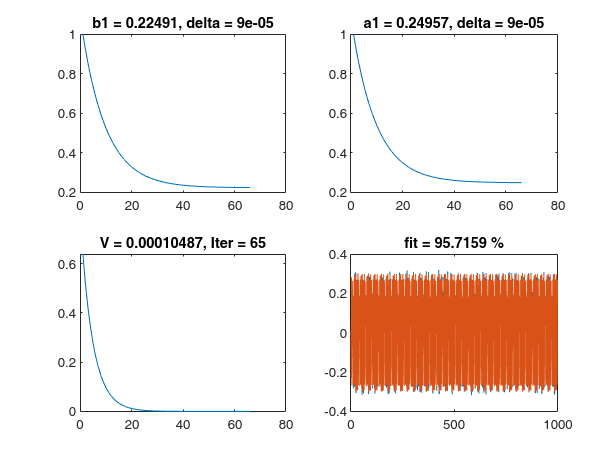

%% Método numérico de Newton-Raphson con modelo ARX112
% Longitud constante del paso
alpha0 = 0.1;
% Número máximo de iteraciones
M = 1000;
a1 = zeros(1,M); b1 = zeros(1,M); V = zeros(1,M);
% Valores iniciales para a1 y b1
a1(1) = 1;  b1(1) = 1;
% Criterio de parada según exactitud de los parámetros
tol = 1e-4;
% Criterio de parada según función de coste
Vmin = 1e-4;
iter = 0;

for i=1:M-1
    % Inicializamos la función de costo y las derivadas
    V1 = 0; S1 = 0; S2 = 0; S3 = 0; S4 = 0; S5 = 0;
    for j=3:N
        % Actualizamos el error
        e = y(j) + a1(i)*y(j-1) - b1(i)*u(j-2);
        % Las primeras derivadas de la función de costo con respecto a
        % los parámetros a1 y b1.
        S1 = S1 + e*y(j-1); S2 = S2 + e*u(j-2);
        % Las segundas derivadas de la función de costo con respecto a
        % los parámetros a1 y b1.
        S3 = S3 + y(j-1)^2; S4 = S4 + u(j-2)^2;
        % Las derivadas cruzadas de la función de costo con respecto a
        % los parámetros a1 y b1 (Que al ser simetrico el Hessiano) son
        % iguales.
        S5 = S5 + y(j-1)*u(j-2);
        % Actualizamos la función de costo según el método MSE
        V1 = V1 + e^2;
    end
    % Vamos llenando el arrgle de la función de costo.
    V(i) = V1/N;
    % Verificamos si el valor de la función de costo actual es menor al
    % valor de parada establecido.
    if V(i) < Vmin
        % Y en caso de que sí, recortamos los arreglos
        a1 = a1(1:i);
        b1 = b1(1:i);
        % Actualizamos la función de costo y el número de iteraciones
        V = V1 + e^2;
        iter = i;
        % Rompemos el ciclo pues el valor de parada fue alcanzado.
        break
    end
    % Calculamos el valor de ∆x
    Vd2 = inv(2/N * [S3 -S5; -S5 S4]);
    % Actualizamos los parámetros a1 y b1, para seguir buscando.
    a1(i+1) = a1(i) - alpha0*Vd2(1,:)*2/N*[S1;-S2];
    b1(i+1) = b1(i) - alpha0*Vd2(2,:)*2/N*[S1;-S2];
    % Verificamos que no se supere el criterio de parada de exactitud de
    % los parámetros
    if((abs(a1(i+1)-a1(i)) <= tol) && (abs(b1(i+1)-b1(i)) <= tol))
        % En caso de que sí, recortamos los arreglos
        a1 = a1(1:i+1);
        b1 = b1(1:i+1);
        % Actualizamos la función de costo y el número de iteraciones
        V1 = 0;
        iter = i+1;
        % Y se recalcula el error con los nuevos parámetros para luego
        % recalcular la función de costo para la cantidad de datos
        % experimentales.
        for j=3:N
            e = y(j) + a1(i+1)*y(j-1) - b1(i+1)*u(j-2);
            V1 = V1 + e^2;
        end
        V(i+1) = V1/N;
        V = V(1:i+1);
        break
    end
end

%% Simulación de los resultados con los parámetros optimizados.
[yest, t] = lsim(tf(b1(iter), [1 a1(iter)], 'Ts', 1, 'InputDelay',1), u, (0:1:N-1));
% Calculamos el valor porcemtual del fit para poder medir el desempeño
% del método en la calidad de la aproximación.
fit = (1 - norm(y - yest) / norm(y - mean(y)))*100;
%% Se grafican los resultados.
subplot(2,2,1), plot(b1), title(['b1 = ' num2str(b1(iter)) ', delta = ' num2str(abs(b1(iter)-b1(iter-1)),1)])
subplot(2,2,2), plot(a1), title(['a1 = ' num2str(a1(iter)) ', delta = ' num2str(abs(a1(iter)-a1(iter-1)),1)])
subplot(2,2,3), plot(V), title(['V = ' num2str(V(i)), ', Iter = ' num2str(i)])
subplot(2,2,4), plot(t,y,t,yest), title(['fit = ' num2str(fit) ' %'])